MATPOWERをインストール後にご実行ください。

### Case9の潮流計算実行

clear

% 1. MATPOWERのケースを読み込んで実行
mpc = loadcase('case9');
results = runpf(mpc);


MATPOWER Version 8.1, 12-Jul-2025
Power Flow -- AC-polar-power formulation

Newton's method converged in 4 iterations.
PF successful

Converged in 0.25 seconds
|     System Summary                                                           |

How many?                How much?              P (MW)            Q (MVAr)
---------------------    -------------------  -------------  -----------------
Buses              9     Total Gen Capacity     820.0        -900.0 to 900.0
Generators         3     On-line Capacity       820.0        -900.0 to 900.0
Committed Gens     3     Generation (actual)    319.6              22.8
Loads              3     Load                   315.0             115.0
  Fixed            3       Fixed                315.0             115.0
  Dispatchable     0       Dispatchable          -0.0 of -0.0      -0.0


% 2. グラフ構造の作成 (Fromバス と Toバス の接続)
s = results.branch(:, 1); % From bus
t = results.branch(:, 2); % To bus
G = graph(s, t);


### 電圧を色にしたプロット

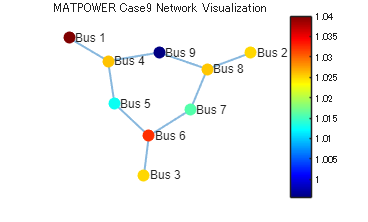

% 3. プロットの作成
figure;
h = plot(G, 'Layout', 'force'); % 力を利用した自動配置（画像に近い見た目になります）

% 4. データの抽出と色の設定（例：バス電圧 Magnitude を色にする場合）
V_mag = results.bus(:, 8); % VM: Voltage Magnitude
labels = cellstr(num2str(results.bus(:, 1), 'Bus %d'));

% 5. 見た目のカスタマイズ
h.MarkerSize = 8;
h.NodeCData = V_mag;      % ノードの色を電圧値に設定
h.LineWidth = 1.5;        % 線の太さ
h.NodeLabel = labels;     % ラベル表示

% カラーバーの設定（画像のようなグラデーション）
colormap('jet'); 
colorbar;
title('MATPOWER Case9 Network Visualization');
grid off;
axis off;

### 有効電力の需要を色にしたプロット

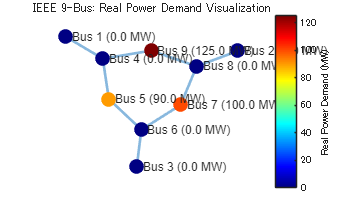

% 3. プロットの作成
figure;
h = plot(G, 'Layout', 'force'); 

% 4. データの抽出と色の設定（有効電力需要 Pd を抽出）
% results.bus(:, 3) は Pd: Real Power Demand (MW)
P_demand = results.bus(:, 3); 

% ラベルにバス番号と需要(MW)を表示するようにカスタマイズ
labels = cell(size(results.bus, 1), 1);
for i = 1:size(results.bus, 1)
    labels{i} = sprintf('Bus %d\n(%.1f MW)', results.bus(i,1), P_demand(i));
end

% 5. 見た目のカスタマイズ
h.MarkerSize = 10;
h.NodeCData = P_demand;    % 需要電力を色に設定
h.LineWidth = 2;
h.NodeLabel = labels;      % 数値付きラベルを適用

% カラーバーの設定
colormap('jet'); 
c = colorbar;
c.Label.String = 'Real Power Demand (MW)';
title('IEEE 9-Bus: Real Power Demand Visualization');
grid off;
axis off;

© 2026 The MathWorks, Inc.